alp = 0.4;
burst = 500;
EbN0_db = 0:0.2:10;
EbN0_n = 10.^(EbN0_db/10);
BER_t = qfunc(sqrt(2*EbN0_n));
BER = zeros(burst,length(BER_t));
sym_rate = 4.8e3;
k = 8;               % oversampling_factor
M = 4;               % M-PSK modulation
N = 2048;            % No. of symbols

%Fixed point Parameters
wordLength = 12;         
fractionLength = 7;

Ts = 1/sym_rate;     % Symbol period
T = Ts/k;            % Sampling period
F = k*sym_rate;
t = -5*Ts : T : 5*Ts;
srrc_fp = zeros(size(t));
for i = 1:1:length(t)
    if t(i) == 0
        srrc_fp(i) = 1 - alp + (4 * alp / pi);
    elseif abs(t(i)) == Ts/(4*alp)
        srrc_fp(i) = (alp/sqrt(2))*((1 + 2/pi)*sin(pi/(4*alp)) + (1 - 2/pi)*cos(pi/(4*alp)));
    else
        srrc_fp(i) = (sin(pi*(1-alp)*t(i)/Ts) + (4*alp*t(i)/Ts)*cos(pi*(1+alp)*t(i)/Ts)) / ((pi*t(i)/Ts)*(1 - (4*alp*t(i)/Ts)^2));
    end
end
srrc = fi(srrc_fp, 1, wordLength, fractionLength, 'SumMode', 'SpecifyPrecision', 'SumWordLength', wordLength, 'SumFractionLength', fractionLength, 'ProductMode', 'SpecifyPrecision', 'ProductWordLength', wordLength, 'ProductFractionLength', fractionLength);

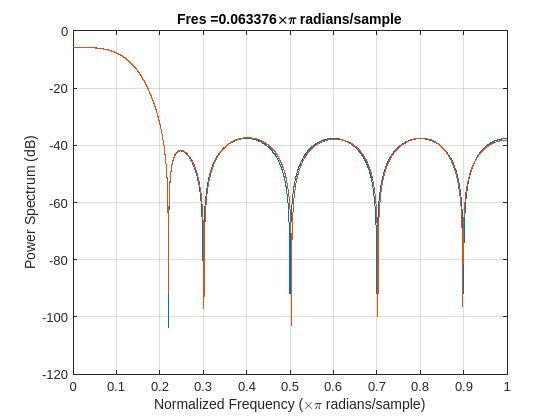

pspectrum(srrc_fp);
hold on
pspectrum(double(srrc));
hold off

for j = 1:1:burst
    inp_signal = randi([0,3],N,1);
    txSig = qpskMod(inp_signal);
    filt_inp = upsample(txSig,k);
    int_sig1 = conv(filt_inp,srrc,'same');
    int_sig2 = conv(int_sig1,srrc,'same');
    [pii,ft] = pwelch(double(int_sig2));
    Ps = bandpower(pii,ft,"psd");
    for i = 1:1:51
        noise = fi(randn(size(int_sig2)) + 1i*randn(size(int_sig2)), 1, wordLength, fractionLength, 'SumMode', 'SpecifyPrecision', 'SumWordLength', wordLength, 'SumFractionLength', fractionLength, 'ProductMode', 'SpecifyPrecision', 'ProductWordLength', wordLength, 'ProductFractionLength', fractionLength);
        awgn = fi(conv(noise,srrc,'same'), 1, wordLength, fractionLength, 'SumMode', 'SpecifyPrecision', 'SumWordLength', wordLength, 'SumFractionLength', fractionLength, 'ProductMode', 'SpecifyPrecision', 'ProductWordLength', wordLength, 'ProductFractionLength', fractionLength);
        [pnn,fn] = pwelch(double(awgn));
        Pn = bandpower(pnn,fn,"psd");
        beta = fi(sqrt(Ps/(Pn*2*EbN0_n(i))), 1, wordLength, fractionLength, 'SumMode', 'SpecifyPrecision', 'SumWordLength', wordLength, 'SumFractionLength', fractionLength, 'ProductMode', 'SpecifyPrecision', 'ProductWordLength', wordLength, 'ProductFractionLength', fractionLength);
        awgn = beta*awgn;
        filt_out = int_sig2 + awgn;
        rxSig = downsample(filt_out,k);
        out_signal = qpskDemod(rxSig);
        BER(j,i) = sum(out_signal ~= inp_signal)/N;
    end
end
BER_f = mean(BER);

figure;
semilogy(EbN0_db, BER_t, 'r', 'LineWidth', 2); % Theoretical BER
hold on;
semilogy(EbN0_db, BER_f, 'b', 'LineWidth', 2);   % Simulated BER
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
legend('Theoretical BER', 'Simulated BER');
title('BER Performance of QPSK over AWGN Channel');
grid on;